# Exercise 2: Create a network from scratch and train 

Create new deep networks for image classification and regression tasks by defining the network architecture and training the network from scratch.

After defining the network architecture, you can define training parameters using the [`trainingOptions`](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html) function. You can then train the network using the [`trainnet`](https://www.mathworks.com/help/deeplearning/ref/trainnet.html) function. Use the trained network to predict class labels or numeric responses. If the [`trainingOptions`](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html) function does not provide the training options that you need for your task, or custom output layers do not support the loss functions that you need, then you can define a custom training loop.

You can train a neural network on a CPU, a GPU, multiple CPUs or GPUs, or in parallel on a cluster or in the cloud. Training on a GPU or in parallel requires Parallel Computing Toolbox™. Using a GPU requires a supported GPU device (for information on supported devices, see [GPU Computing Requirements](https://www.mathworks.com/help/parallel-computing/gpu-computing-requirements.html) (Parallel Computing Toolbox)). Specify the execution environment using the [`trainingOptions`](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html) function.

## Design network layers

Create new deep networks for tasks such as image classification and regression by defining the network architecture from scratch. Build networks using MATLAB or interactively using [Deep Network Designer](https://www.mathworks.com/help/deeplearning/ref/deepnetworkdesigner-app.html).

For most tasks, you can use built-in layers. If there is not a built-in layer that you need for your task, then you can define your own custom layer. You can define custom layers with learnable and state parameters. After you define a custom layer, you can check that the layer is valid, GPU compatible, and outputs correctly defined gradients. For a list of supported layers, see [List of Deep Learning Layers](https://www.mathworks.com/help/deeplearning/ug/list-of-deep-learning-layers.html).

For models that cannot be specified as networks of layers, you can define the model as a function. To learn more, see [Define Custom Training Loops, Loss Functions, and Networks](https://www.mathworks.com/help/deeplearning/ug/define-custom-training-loops-loss-functions-and-networks.html).

layers = [
    imageInputLayer([8 8 1])
    %featureInputLayer(1,Normalization="zscore")
    
    convolution2dLayer(3,8,Padding="same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,Stride=2)
    
    convolution2dLayer(3,16,Padding="same")
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,Stride=2)
    
    convolution2dLayer(3,32,Padding="same")
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(4)
    softmaxLayer];

## Split data into training and testing portions

%% set up the dataset entries in workspace
[xTrain, label_Train, xTest, label_Test] = trainWithTabularData(dataTable);

## Set up training options


% Start with simple options
options = trainingOptions("lbfgs", ...
    ExecutionEnvironment="cpu", ...
    Plots="training-progress", ...
    ValidationData={xTest, label_Test}, ...
    Verbose=false);


## Train and validate easily

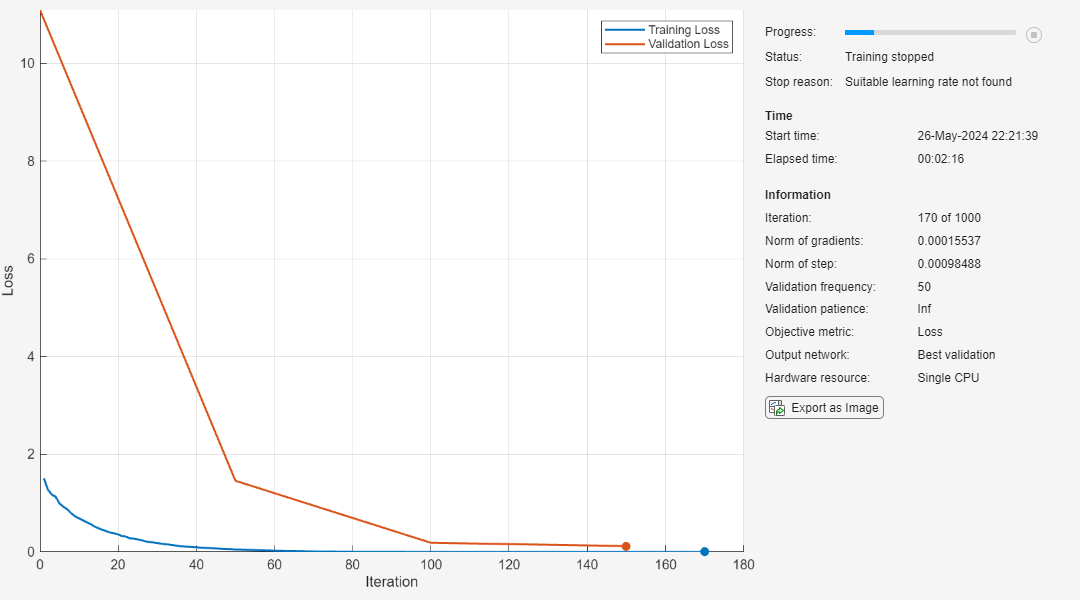

%% train one network
net = trainnet(xTrain,label_Train,layers,"crossentropy",options);

save("ex2TrainedNet.mat", "net"); 

## Test the network inference

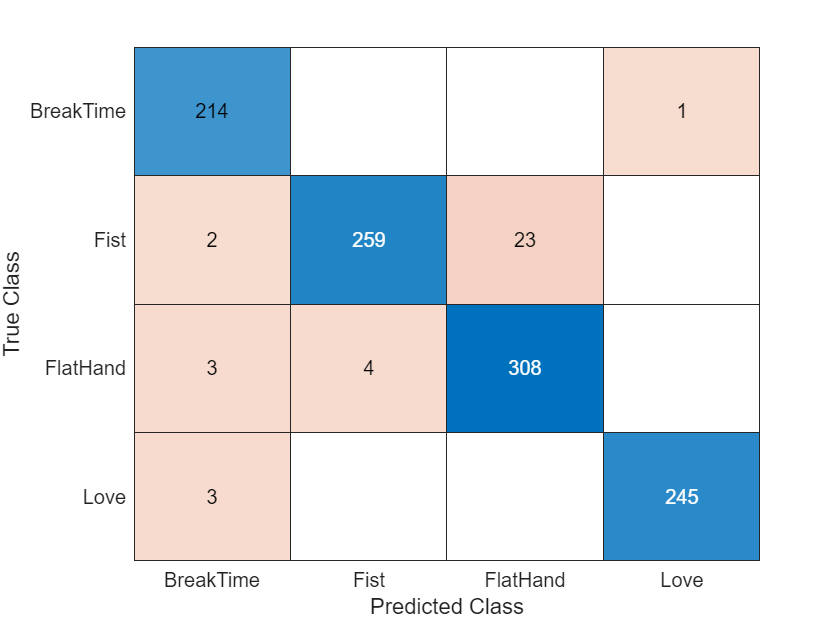

%% test the trained network
scoresTest = minibatchpredict(net,xTest);
YTest = onehotdecode(scoresTest,classNames,2);
confusionchart(label_Test,YTest);

accuracy = mean(YTest == label_Test)

accuracy = 0.9661